# Load images and reference

% move to main folder before running script

run('config\run_at_startup.m')

filefolder = 'data\raw\testdata';
filepaths = fullfile(filefolder,'21-xyc-ex405nm_em415-10-735_kaolinite_GSH-CD_pH3.nd2');
nFiles = 1;

filenamereference = fullfile(filefolder,'0-xyc-ex405nm_em415-10-735_interlock-on_dark.nd2');
cl = CLSMspectraLab(filepaths);

Reading series #1
    ................................


creference = CLSMspectraLab(filenamereference);

Reading series #1
    ................................


## Background Correction and masking

cl = cl.computeMask;

Computed mask with background correction.


cl.bgCorrection = bgCorrection.reference; % background correction from bgCorrection domain
for ii = 1:nFiles
    cl.bgCorrection(ii).referenceimage = creference.input;
    cl.bgCorrection(ii).uniformBackgroundFlag = true;%
end
cl = cl.computeBgCorrection;

for ii = 1:nFiles
    cl.input(ii).applyMaskImageStack(cl.mask(ii),'sum','x','y');
end


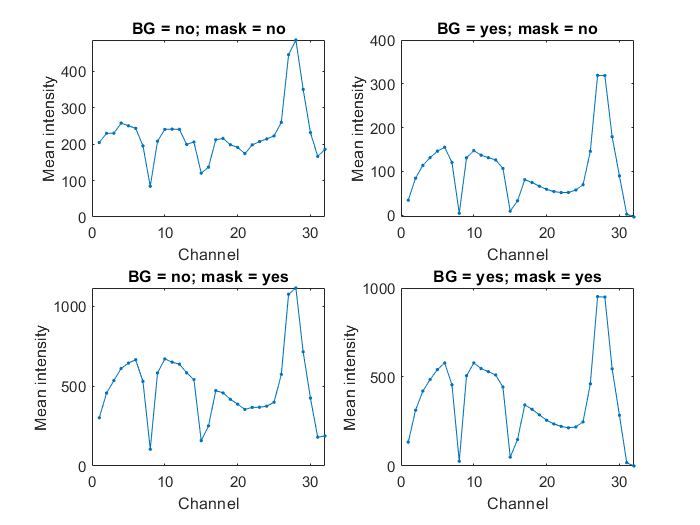

cl.bgCorrectionFlag = false;
cl.maskFlag = false;
figure
subplot(2,2,1)
cl.plotChannels
title('BG = no; mask = no')
legend off

cl.bgCorrectionFlag = true;
cl.maskFlag = false;
subplot(2,2,2)
cl.plotChannels
title('BG = yes; mask = no')
legend off

cl.bgCorrectionFlag = false;
cl.maskFlag = true;
subplot(2,2,3)
cl.plotChannels
title('BG = no; mask = yes')
legend off

cl.bgCorrectionFlag = true;
cl.maskFlag = true;
subplot(2,2,4)
cl.plotChannels
title('BG = yes; mask = yes')
legend off

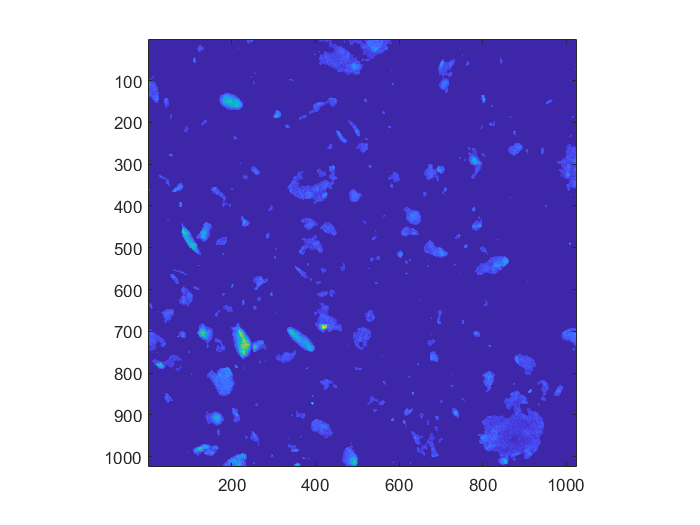


figure
cl.plotSumIntensity2D